# FULL CASE: Data Processing Multiple Trial SimulationsTest File  

**Author: Nina Matthews**

**Project: Masters Dissertation - Hierarchical portfolio stress-testing with flexible probabilities**

**Last edit: 22/11/2023**

**Supervisor: A/Prof. Tim Gebbie**

**Resources Used: **The MathWorks, Inc. (2019) 

## **Purpose**

*****

*****

*****

## **1. Environment Setup **

**Clear Env and Plots**

clc % clear command window
close all %clear all figs
clear % clears workspace

**Source Directories **

Set path to **backtest** function folder

% Add /functions directory
addpath(fullfile(userpath,'/STA5000W DISSERTATION Code/Toolboxes/backtest/functions/'));

Set path to **benchmark** function folder *(Later the benchmark class can become a deriviative class to the backtest class)*

% Add /functions directory
addpath(fullfile(userpath,'/STA5000W DISSERTATION Code/Toolboxes/benchmarks/functions/'));

Set path to **HRP** function folder *(Later the benchmark class can become a deriviative class to the benchmark class)*

% Add /functions directory
addpath(fullfile(userpath,'/STA5000W DISSERTATION Code/Toolboxes/hrp/functions/'));
addpath(fullfile(userpath,'/STA5000W DISSERTATION Code/Toolboxes/hsfp/functions/'));

Set path for processed data

% Add Data source directory
addpath(fullfile(userpath,'/STA5000W DISSERTATION Code/Data/BACKTESTS/'));
% Add Data source directory
addpath(fullfile(userpath,'/STA5000W DISSERTATION Code/Data/PROCESSED/'));

Add path to backtestedPortfolio object: 

addpath '/Users/Ninamatthews/Documents/MATLAB/STA5000W DISSERTATION Code/OOP'

**Export Directories**

Set Image export path:

% use your default user path to create the filename and path
exportName = '';
% Backtest images
imageExportpath = fullfile('/Users/Ninamatthews/Desktop/MASTERS/Images/Backtesting/',exportName);
% Structural test images
imageExportpath_st = fullfile('/Users/Ninamatthews/Desktop/MASTERS/Images/Structural_Testing/',exportName);

Set Output data EXPORT path

dataExportpath = fullfile(userpath,'/STA5000W DISSERTATION Code/Data/BACKTESTS/', exportName);

## 2.1 Load Data: ASSET Log Dif Returns & Sig Data

fileName = 'DATA-PROCESSED-ASSETCL-RETURNS-M-TTABLE-20070731-20230228.mat';
load(fileName)
% Load invariant data for HSFP Prs
fileName = 'DATA-PROCESSED-ASSETCL-INVARIANT-M-TTABLE-20070831-20230228.mat';
load(fileName)
% Load signal data
fileName = 'DATA-PROCESSED-SIG-ADJUSTED-SMTH-3M3Y_NORM-M-TTABLE-20070531-20230228.mat';
load(fileName)

## 2.2 Load Data: Pre-generated simulations and kmeans results

fileName = 'DATA-SIM-3375_BKTST-PERFORMANCE-M-CELL_ARR.mat';
load(fileName)
fileName = 'full_MV_clstrs_BaseKMeansClustered.mat';
load(fileName)
fileName = 'full_HRP_clstrs_BaseKMeansClustered.mat';
load(fileName)

# FULL CASE: DATA PROCESSING HYPER-PARAMETERS

# 15 data points per hyper-parameter

## 3. Set up hyper-parameter ranges (will generalise at a later stage)

Range is created for all hyper parameters that will be varied.

For the data tuning we use: 

- Cash Constriants

- Standard deviation range for Winsorised data

- Regularisation lambda

% CC_range  = linspace(0, 1, 15);
% W_sd_range  = linspace(1, 5, 15);
% Lambda_reg_range = linspace(0, 1, 15);
% hyperparameter_set = [CC_range; W_sd_range; Lambda_reg_range];
% 
% % Initialize an empty matrix to store configurations
% num_configs = size(hyperparameter_set, 2)^size(hyperparameter_set, 1);
% configurations = zeros(num_configs, size(hyperparameter_set, 1));
% 
% % Nested loops to generate all configurations based on the size of hyperparameter_set
% col = 1;
% for config1 = 1:size(hyperparameter_set, 2)
%     for config2 = 1:size(hyperparameter_set, 2)
%         for config3 = 1:size(hyperparameter_set, 2)
%             % Store the current combination of values in the configurations matrix
%             configurations(col, :) = [hyperparameter_set(1, config1); hyperparameter_set(2, config2); hyperparameter_set(3, config3)];
%             col = col + 1;
%         end
%     end
% end

## 4.  Setting up HSFP object and Backtest object:

- Need to initialise backtestedPortfolio object (has built in defaults)

-  Initialise HSFPparameters object (has built in defaults)

- Need to provide Returns

- Assign HSFP parameters to backtestPortfolio

- Choose a method (defualt is 'None)

- If method is anything other than 'none' user needs to assign Signals Timetable

### Default Model with no changes:

% CC = 1; % no constraint if == 1
% W_sd = []; % exclude if no winsorising is wanted
% HSFPparameters_test = HSFPparameters;
% HSFPparameters_test.Tau_prior = 36;
% test_class1 = backtestedPortfolios;
% test_class1.HSFPparameters = HSFPparameters_test;
% test_class1.Returns = M_Ret_TT;
% test_class1.Method =  'none';
% test_class1.Signals = timetable(SIG_SMOOTHED_TT.Time, SIG_SMOOTHED_TT.SAVIT40_Index, SIG_SMOOTHED_TT.lagged_SACPIYOY_Index);
% test_class1.WinsorStd = W_sd;
% test_class1.CashConstriant = CC;
% test_class1.RegLambda = 0.00;
% 
% %%% Run backtest
% test1_bcktest = OOPbacktest_analysis(test_class1);
%%% Plot performance Curves 
% PerformancePlot(test1_bcktest);

## 5. Simulation Loop for changing hyper parameters

### 5.1 Test without parallisation 

% profile on
% data_processing_config_sim_cellArr = simulate_backtest(configurations,test_class1);
% profile off

% profile viewer

### 5.2 Using parellel computing

% tic
% data_processing_config_sim_cellArr = para_simulate_backtest(configurations,test_class1);
% toc

**SAVE Simulation Cell Array:**

% sim_filename = ['DATA-SIM_FULL-', num2str(num_configs), '_BKTST-PERFORMANCE-M-CELL_ARR.mat'];
% save(fullfile(dataExportpath,sim_filename),'data_processing_config_sim_cellArr');

## 6. Visualise Simulations

### 6.1 Visualise MV Simulations

% % Create a new figure for the plot
% figure('InnerPosition', [100, 100, 600, 600]);
% % Iterate through each timetable in the cell array and plot it
% for i = 1:numel(data_processing_config_sim_cellArr)
%     subplot(1, 1, 1);  % Define the subplot layout as needed
%     plot(data_processing_config_sim_cellArr{i}.RollingPerformance.Time, data_processing_config_sim_cellArr{i}.RollingPerformance.("MVSR max"));  
%     hold on;
% end
% 
% % Customize the plot as needed
% ylim([1, 5.5]);
% title(['Full Case MV Portfolio Simulations: ',num2str(num_configs), ' Trails'],'FontSize', 14);
% xlabel('Time','FontSize', 15);
% ylabel('Price Index','FontSize', 15);  % Adjust the ylabel as needed
% 
% FULL_MV_BCKTST_SIM_Performance_plot = gcf;
% 
% % Release hold so that future plots won't overlay
% hold off; 

**Export FULL MV Simulations plot**

% exportName = 'FULL_MV_BCKTST_SIM_Performance_plot.pdf';
% exportgraphics(FULL_MV_BCKTST_SIM_Performance_plot,fullfile(imageExportpath,exportName),'Resolution',600);

### 6.2 Visualise HRP Simulations

% % Create a new figure for the plot
% figure('InnerPosition', [100, 100, 600, 600]);
% % Iterate through each timetable in the cell array and plot it
% for i = 1:numel(data_processing_config_sim_cellArr)
%     subplot(1, 1, 1);  % Define the subplot layout as needed
%     plot(data_processing_config_sim_cellArr{i}.RollingPerformance.Time, data_processing_config_sim_cellArr{i}.RollingPerformance.("HRP"));  
%     hold on;
% end
% 
% % Customize the plot as needed
% ylim([1, 5.5]);
% title(['Full Case HRP Portfolio Simulations: ',num2str(num_configs), ' Trails'],'FontSize', 14);
% xlabel('Time','FontSize', 15);
% ylabel('Price Index','FontSize', 15);  % Adjust the ylabel as needed
% 
% FULL_HRP_BCKTST_SIM_Performance_plot = gcf;
% 
% % Release hold so that future plots won't overlay
% hold off; 

**Export FULL MV Simulations plot**

% exportName = 'FULL_HRP_BCKTST_SIM_Performance_plot.pdf';
% exportgraphics(FULL_HRP_BCKTST_SIM_Performance_plot,fullfile(imageExportpath,exportName),'Resolution',600);

## 7. Extract Excess Returns from simulations to cluster

data_processing_sim_ExcessRet_cellArr  = extractSimExcessRet(data_processing_config_sim_cellArr);

**SAVE MV & HRP Simulated Excess Returns:**

% sim_filename = 'DATA-SIM_FULL-BKTST_MV_HRP-EXCESS_RET-M-CELL_ARR.mat';
% save(fullfile(dataExportpath,sim_filename),'data_processing_sim_ExcessRet_cellArr');

### 7.1 Visualise Excess Return Series

#### 7.1.1 Plot MV simulated Excess Returns 

% Assuming myTimetable is your timetable object
figure('InnerPosition', [100, 100, 600, 600]);
myTimetable = data_processing_sim_ExcessRet_cellArr{2,1};

% Iterate through each variable in the timetable
for i = 1:width(myTimetable)
    plot(myTimetable.Time, myTimetable{:, i});
    
    % Customize the plot, e.g., set labels, titles, etc.
    ylim([-0.2, 0.2]);
    title(['Full Case MV Portfolio: ',num2str(width(myTimetable)), ' Trails'],'FontSize', 14);
    xlabel('Time','FontSize', 15);
    ylabel('Returns','FontSize', 15);
    hold on; % Hold for overlaying plots
    FULL_MV_Realised_Ret_Plot = gcf;

end
hold off;

**Export FULL MV Simulations Realised Returns plot**

exportName = 'FULL_MV_Realised_Ret_Plot.pdf';
exportgraphics(FULL_MV_Realised_Ret_Plot,fullfile(imageExportpath,exportName),'Resolution',300);

#### 7.1.2 Plot HRP simulated Excess Returns 

% Assuming myTimetable is your timetable object
figure('InnerPosition', [100, 100, 600, 600]);
myTimetable = data_processing_sim_ExcessRet_cellArr{2,2};

% Iterate through each variable in the timetable
for i = 1:width(myTimetable)
    plot(myTimetable.Time, myTimetable{:, i});
    
    % Customize the plot, e.g., set labels, titles, etc.
   title(['Full Case HRP Portfolio: ',num2str(width(myTimetable)), ' Trails'],'FontSize', 14);
    xlabel('Time','FontSize', 15);
    ylabel('Returns','FontSize', 15);
    hold on; % Hold for overlaying plots
    FULL_HRP_Realised_Ret_Plot = gcf;

end
hold off;

**Export FULL HRP Simulations Realised Returns plot**

exportName = 'FULL_HRP_Realised_Ret_Plot.pdf';
exportgraphics(FULL_HRP_Realised_Ret_Plot,fullfile(imageExportpath,exportName),'Resolution',300);

## 8. Kmeans applied to corr matrix

### 8.1 Correlation matrix of the excess returns:

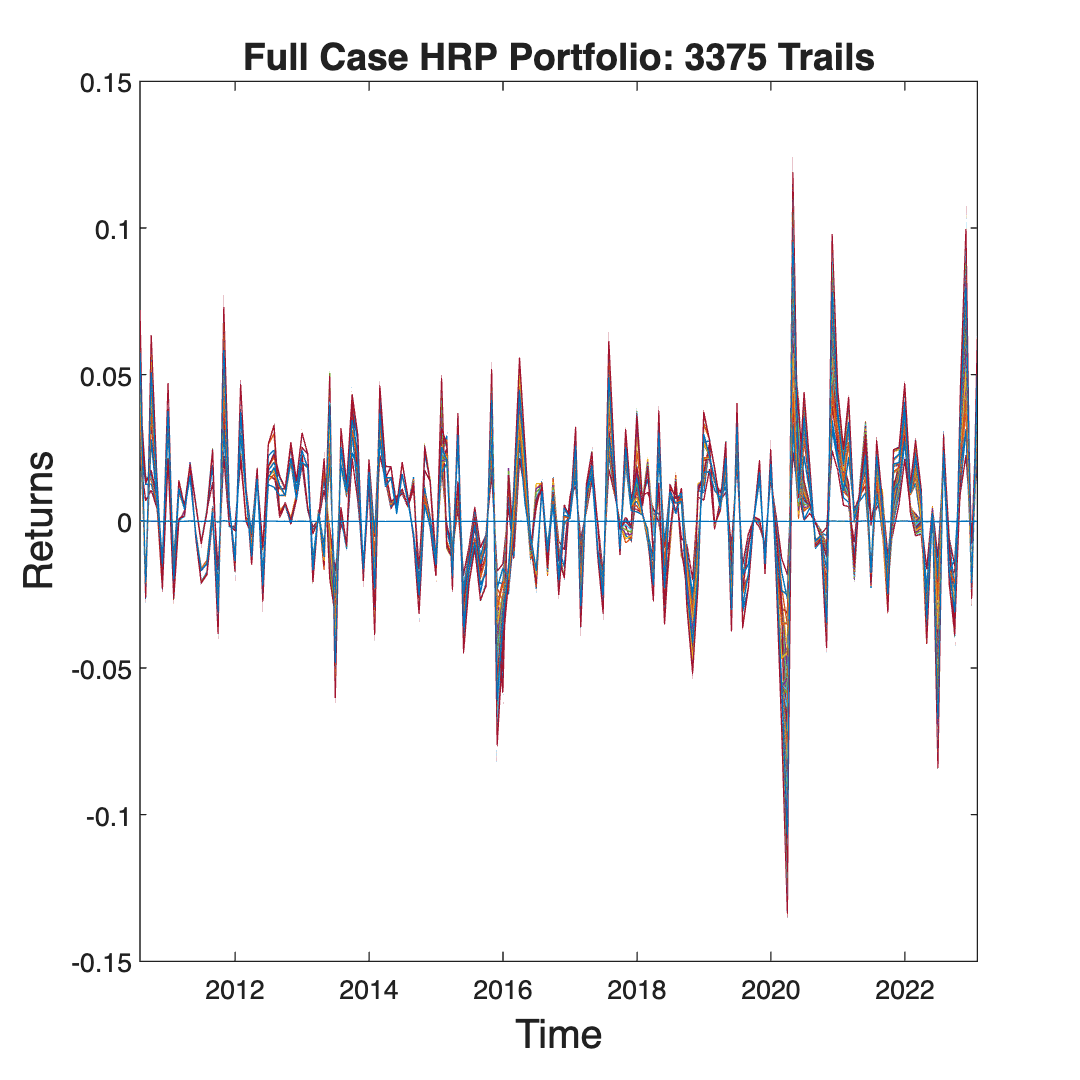

% FULL_MV_sim_corMatrix = corrcoef(table2array(data_processing_sim_ExcessRet_cellArr{2,1}));
% FULL_HRP_sim_corMatrix = corrcoef(table2array(data_processing_sim_ExcessRet_cellArr{2,2}));

### 8.2 Apply KMeans

% tic
% [FULL_MVcorr, full_MV_clstrs, FULL_MVsilh2] = clusterKMeansBase(FULL_MV_sim_corMatrix, 30, 30);
% [FULL_HRPcorr, full_HRP_clstrs, FULL_HRPsilh2] = clusterKMeansBase(FULL_HRP_sim_corMatrix, 30, 30);
% toc

### 8.3 Apply PAM clustering

% tic
% [PAM_MVcorr, PAM_MVclstrs2, PAM_MVsilh2] = clusterPAMBase(FULL_MV_sim_corMatrix, 30, 30);
% [PAM_HRPcorr, PAM_HRPclstrs2, PAM_HRPsilh2] = clusterPAMBase(FULL_HRP_sim_corMatrix, 30, 30);
% toc

% convert char to double for each inner cell
for clst = 1:length(keys(full_MV_clstrs))
    full_MV_clstrs{clst} = cellfun(@(x) str2double(x), full_MV_clstrs{clst});
end

for clst = 1:length(keys(full_HRP_clstrs))
    full_HRP_clstrs{clst} = cellfun(@(x) str2double(x), full_HRP_clstrs{clst});
end

- Need the covar matrix per cluster.

- Need to extract idices for each cluster

- pull series from each cluster 

- calc cov of series

## 3.1 MV Realised Return Paths subsetted for each cluster

% Store Realised Returns for MV in matrix for easy indexing
num_clst_MV = length(keys(full_MV_clstrs));
FULL_MV_Ret_matrix = table2array(data_processing_sim_ExcessRet_cellArr{2,1});
% storage for cluster members
FULL_MVclstr_memb_Ret_cellArr = cell(2,num_clst_MV);

for clst = 1:num_clst_MV
    % Number clusters in cell array
    FULL_MVclstr_memb_Ret_cellArr{1,clst} = clst;
    % Member index per cluster
    FULL_MVclstr_memb = full_MV_clstrs{clst};
    % Extract indexed columns from matrix
    FULL_MVclstr_memb_subset = FULL_MV_Ret_matrix(:, FULL_MVclstr_memb);
    % assign subsetted matrix to cell array per cluster
    FULL_MVclstr_memb_Ret_cellArr{2,clst} = FULL_MVclstr_memb_subset;
end

## 3.2 HRP Realised Return Paths subsetted for each cluster

% Store Realised Returns for MV in matrix for easy indexing
num_clst_HRP = length(keys(full_HRP_clstrs));
FULL_HRP_Ret_matrix = table2array(data_processing_sim_ExcessRet_cellArr{2,2});
% storage for cluster members
FULL_HRPclstr_memb_Ret_cellArr = cell(2,num_clst_HRP);

for clst = 1:num_clst_HRP
    % Number clusters in cell array
    FULL_HRPclstr_memb_Ret_cellArr{1,clst} = clst;
    % Member index per cluster
    FULL_HRPclstr_memb = full_HRP_clstrs{clst};
    % Extract indexed columns from matrix
    FULL_HRPclstr_memb_subset = FULL_HRP_Ret_matrix(:, FULL_HRPclstr_memb);
    % assign subsetted matrix to cell array per cluster
    FULL_HRPclstr_memb_Ret_cellArr{2,clst} = FULL_HRPclstr_memb_subset;
end

## 4.1 MV: Correlation for each cluster and reweighting of paths wityhin clusters

% Time table storage for new series
FULL_MV_Rewted_Cluster_Ret_TT = timetable(data_processing_sim_ExcessRet_cellArr{2,1}.Time);
for clst = 1:num_clst_MV
    %%% If only single path in cluster presewrve that path and dont reweight
    if width(FULL_MVclstr_memb_Ret_cellArr{2,clst}) > 1
        % calc covariance per cluster
        cst_cov =cov(FULL_MVclstr_memb_Ret_cellArr{2,clst});
        % Get rebalancing weights
        cst_ivp = clusterIVP(cst_cov,true);
        % Reweight the series into a single series
        S_wted = FULL_MVclstr_memb_Ret_cellArr{2,clst} * cst_ivp;
        % Convert the T x 1 double to a table and add it as a column to the new timetable
        FULL_MV_Rewted_Cluster_Ret_TT = addvars(FULL_MV_Rewted_Cluster_Ret_TT, S_wted);
    else
        FULL_MV_Rewted_Cluster_Ret_TT = addvars(FULL_MV_Rewted_Cluster_Ret_TT, FULL_MVclstr_memb_Ret_cellArr{2,clst}); 
    end 
end

## 4.2 HRP: Correlation for each cluster and reweighting of paths wityhin clusters

% Time table storage for new series
FULL_HRP_Rewted_Cluster_Ret_TT = timetable(data_processing_sim_ExcessRet_cellArr{2,2}.Time);
for clst = 1:num_clst_HRP
      %%% If only single path in cluster presewrve that path and dont reweight
     if width(FULL_HRPclstr_memb_Ret_cellArr{2,clst}) > 1
        % calc covariance per cluster
        cst_cov =cov(FULL_HRPclstr_memb_Ret_cellArr{2,clst});
        % Get rebalancing weights
        cst_ivp = clusterIVP(cst_cov, true);
        % Reweight the series into a single series
        S_wted = FULL_HRPclstr_memb_Ret_cellArr{2,clst} * cst_ivp;
        % Convert the T x 1 double to a table and add it as a column to the new timetable
        FULL_HRP_Rewted_Cluster_Ret_TT = addvars(FULL_HRP_Rewted_Cluster_Ret_TT, S_wted);
     else
        FULL_HRP_Rewted_Cluster_Ret_TT = addvars(FULL_HRP_Rewted_Cluster_Ret_TT, FULL_HRPclstr_memb_Ret_cellArr{2,clst}); 
     end 
end

### MV: Plot Reduced Realise Returns profile

% Assuming myTimetable is your timetable object
figure('InnerPosition', [100, 100, 600, 600]);

myTimetable = FULL_MV_Rewted_Cluster_Ret_TT;

% Iterate through each variable in the timetable
for i = 1:width(myTimetable)
    plot(myTimetable.Time, myTimetable{:, i});
    
    % Customize the plot, e.g., set labels, titles, etc.
   ylim([-0.2, 0.2]);
   title(['Full Case MV Aggregated Returns: ',num2str(width(myTimetable)), ' Clusters'],'FontSize', 13);
    xlabel('Time','FontSize', 15);
    ylabel('Returns','FontSize', 15);
    hold on; % Hold for overlaying plots
    FULL_MV_Aggregated_Ret_Plot = gcf;
end

**Export FULL MV Simulations plot**

exportName = 'FULL_MV_Aggregated_Ret_Plot.pdf';
exportgraphics(FULL_MV_Aggregated_Ret_Plot,fullfile(imageExportpath,exportName),'Resolution',300);

### HRP: Plot Reduced Realise Returns profile

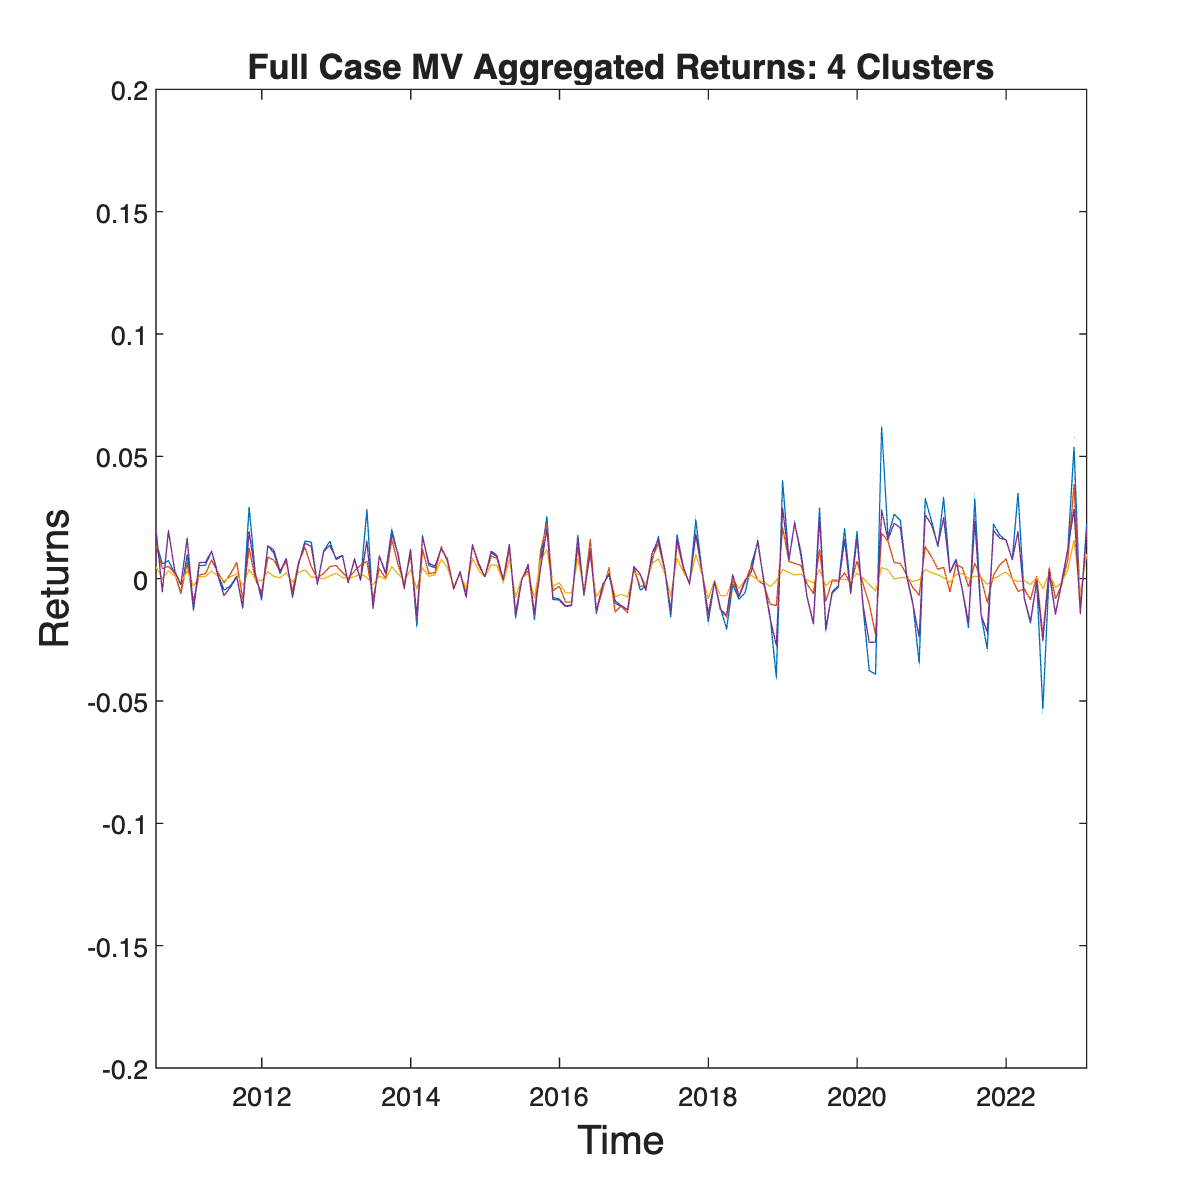

% Assuming myTimetable is your timetable object
figure('InnerPosition', [100, 100, 600, 600]);

myTimetable = FULL_HRP_Rewted_Cluster_Ret_TT;

% Iterate through each variable in the timetable
for i = 1:width(myTimetable)
    plot(myTimetable.Time, myTimetable{:, i});
    
    % Customize the plot, e.g., set labels, titles, etc.
   title(['Full Case HRP Aggregated Returns: ',num2str(width(myTimetable)), ' Clusters'],'FontSize', 13);
    xlabel('Time','FontSize', 15);
    ylabel('Returns','FontSize', 15);

    hold on; % Hold for overlaying plots
    FULL_HRP_Aggregated_Ret_Plot = gcf;
end

**Export FULL MV Simulations plot**

exportName = 'FULL_HRP_Aggregated_Ret_Plot.pdf';
exportgraphics(FULL_HRP_Aggregated_Ret_Plot,fullfile(imageExportpath,exportName),'Resolution',300);

## 5. Calculate Annualised SR per cluster

According to De Prado, Lewis (2019):


$$\widehat{\mathrm{aSR}}_k=\frac{E\left[\left\{S_{k, t}\right\}\right] \text { Frequency }_k}{\sqrt{V\left[\left\{S_{k, t}\right\}\right] \text { Frequency }_k}}=\widehat{\mathrm{SR}}_k \sqrt{\text { Frequency }_k}$$


where,$\text { Frequency }_k=\frac{T_k}{\text { Years }_k}$, and  $\text { Years }_k=\frac{\text { Last Date }_k-\text { First Date }_k}{12 \text { months }}$. 

### 5.1 MV Var[SR]

MV_Aggregated_SR_vec = zeros(num_clst_MV,1);
for clst = 1:num_clst_MV
MV_Aggregated_SR_vec(clst) = geo_sr(FULL_MV_Rewted_Cluster_Ret_TT(:,clst),1);
end
MV_Aggregated_SR_VAR = var(MV_Aggregated_SR_vec)

### 5.1 HRP Var[SR]

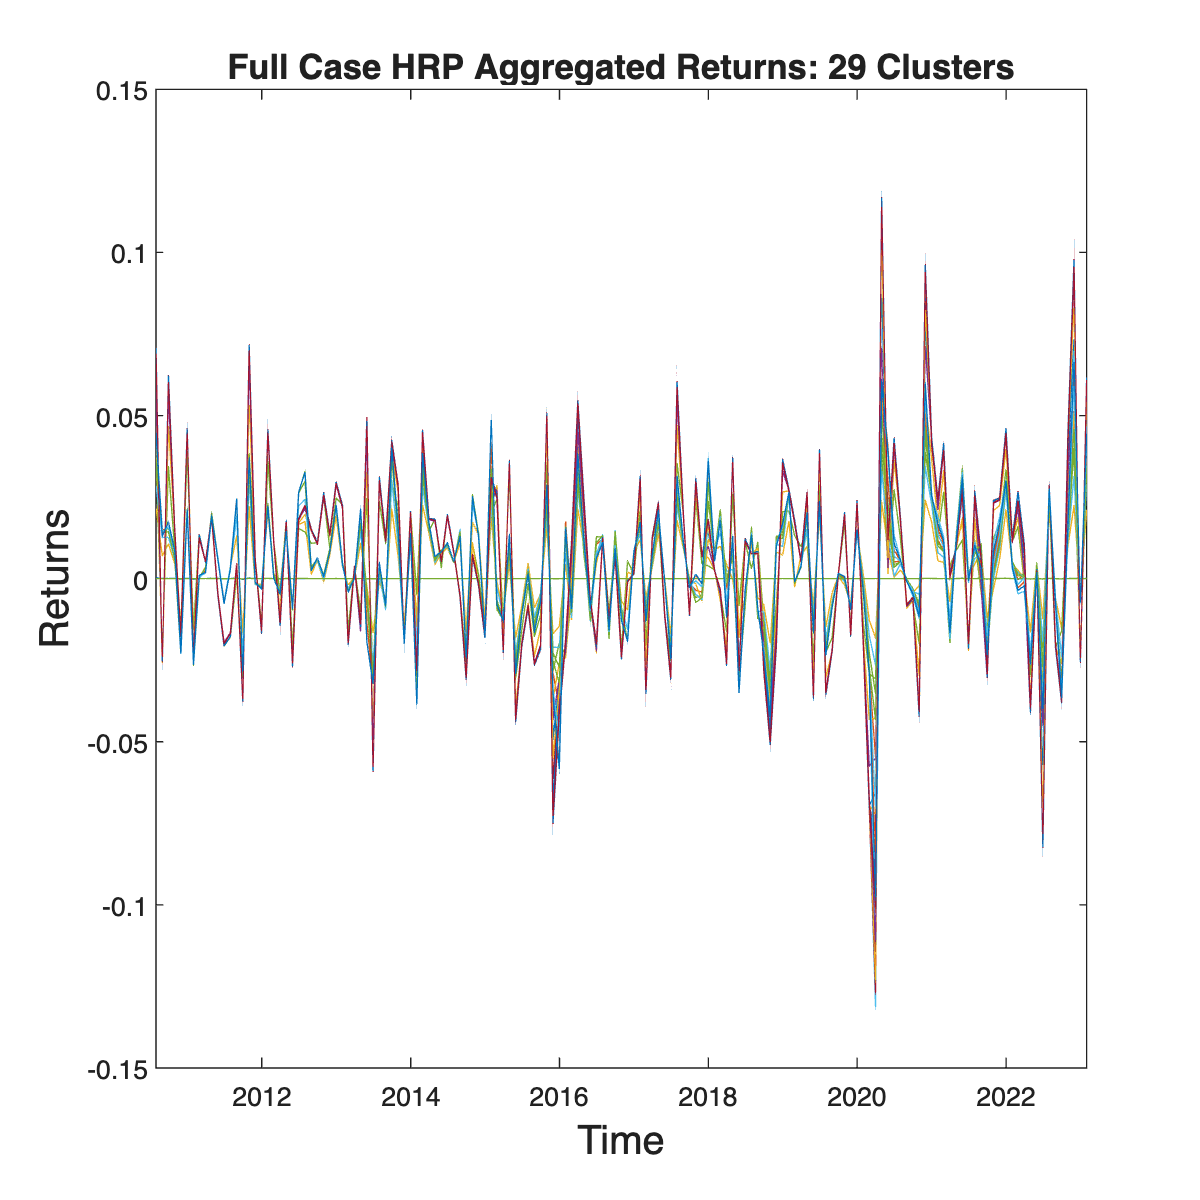

HRP_Aggregated_SR_vec = zeros(num_clst_HRP,1);
for clst = 1:num_clst_HRP

HRP_Aggregated_SR_vec(clst) = geo_sr(FULL_HRP_Rewted_Cluster_Ret_TT(:,clst),1);
end

HRP_Aggregated_SR_VAR = var(HRP_Aggregated_SR_vec)

**Expected Maximum SR: SR***

MVexpected_max_sr = est_max_sr(num_clst_MV, MV_Aggregated_SR_VAR)
HRPexpected_max_sr = est_max_sr(num_clst_HRP, HRP_Aggregated_SR_VAR)

## 6. Calculating DSR for all Variations 

### **NB: We will use the varaince of the MV simulations to cover all possible SR's **

### 1. Unadjusted 

Define the portfolios to calcualte DSR for: eg selected cash constraints, reg lambdas etc

CC = 1; % no constraint if == 1

MV_Aggregated_SR_VAR = 3.8194e-04

W_sd = []; % exclude if no winsorising is wanted
HSFPparameters_test = HSFPparameters;
HSFPparameters_test.Tau_prior = 36;
test_class1 = backtestedPortfolios;
test_class1.HSFPparameters = HSFPparameters_test;
test_class1.Returns = M_Ret_TT;
test_class1.Method =  'none';
test_class1.Signals = timetable(SIG_SMOOTHED_TT.Time, SIG_SMOOTHED_TT.SAVIT40_Index, SIG_SMOOTHED_TT.lagged_SACPIYOY_Index);

HRP_Aggregated_SR_VAR = 7.9971e-04

test_class1.WinsorStd = W_sd;
test_class1.CashConstriant = CC;
test_class1.RegLambda = 0.00;

MVexpected_max_sr = 0.0206

unadjsuted_bcktest = OOPbacktest_analysis(test_class1);

HRPexpected_max_sr = 0.0582

Sub SR* into PSR to calculated DSR:

% MV_unadjusted_dsr = psr(unadjsuted_bcktest.ExcessReturns(:,2), MVexpected_max_sr)
% HRP_unadjusted_dsr = psr(unadjsuted_bcktest.ExcessReturns(:,4), HRPexpected_max_sr)

unadjusted_bcktest = OOPbacktest_analysis(unadjsuted_bcktest);

Sub SR* into PSR to calculated DSR:

MV_unadjsuted_dsr = psr(unadjusted_bcktest.ExcessReturns(:,2), MVexpected_max_sr)
HRP_unadjusted_dsr = psr(unadjusted_bcktest.ExcessReturns(:,4), MVexpected_max_sr)

NonHSFP_Uadjusted_SurfPlot = OptControlPlot(unadjsuted_bcktest);

UnAdj_36RollW_Output_Plot = PerformancePlot(unadjsuted_bcktest);

**Export **

exportName = 'UnAdj_36RollW_Output_Plot.pdf';
exportgraphics(UnAdj_36RollW_Output_Plot,fullfile(imageExportpath,exportName),'Resolution',300);

### 2. CC 

Define the portfolios to calcualte DSR for: eg selected cash constraints, reg lambdas etc

CC = 0.05; % no constraint if == 1
W_sd = []; % exclude if no winsorising is wanted
HSFPparameters_test = HSFPparameters;
HSFPparameters_test.Tau_prior = 36;
test_class2 = backtestedPortfolios;
test_class2.HSFPparameters = HSFPparameters_test;
test_class2.Returns = M_Ret_TT;
test_class2.Method =  'none';
test_class2.Signals = timetable(SIG_SMOOTHED_TT.Time, SIG_SMOOTHED_TT.SAVIT40_Index, SIG_SMOOTHED_TT.lagged_SACPIYOY_Index);
test_class2.WinsorStd = W_sd;
test_class2.CashConstriant = CC;
test_class2.RegLambda = 0.00;

CC_bcktest = OOPbacktest_analysis(test_class2);

MV_unadjsuted_dsr = 0.6229

Sub SR* into PSR to calculated DSR:

MV_CC_dsr = psr(CC_bcktest.ExcessReturns(:,2), MVexpected_max_sr)

HRP_unadjusted_dsr = 0.9688

HRP_CC_dsr = psr(CC_bcktest.ExcessReturns(:,4), MVexpected_max_sr)

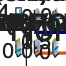

CC5_36RollW_Output_Plot = PerformancePlot(CC_bcktest);

**Export **

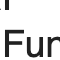

exportName = 'CC5_36RollW_Output_Plot.pdf';

exportgraphics(CC5_36RollW_Output_Plot,fullfile(imageExportpath_st,exportName),'Resolution',300);

### 3. W 

Define the portfolios to calcualte DSR for: eg selected cash constraints, reg lambdas etc

CC = 1; % no constraint if == 1
W_sd = 2; % exclude if no winsorising is wanted
HSFPparameters_test = HSFPparameters;
HSFPparameters_test.Tau_prior = 36;
test_class3 = backtestedPortfolios;
test_class3.HSFPparameters = HSFPparameters_test;
test_class3.Returns = M_Ret_TT;
test_class3.Method =  'none';
test_class3.Signals = timetable(SIG_SMOOTHED_TT.Time, SIG_SMOOTHED_TT.SAVIT40_Index, SIG_SMOOTHED_TT.lagged_SACPIYOY_Index);
test_class3.WinsorStd = W_sd;
test_class3.CashConstriant = CC;
test_class3.RegLambda = 0.00;

W_bcktest = OOPbacktest_analysis(test_class3);

Sub SR* into PSR to calculated DSR:

MV_W_dsr = psr(W_bcktest.ExcessReturns(:,2), MVexpected_max_sr)

MV_CC_dsr = 0.8140

HRP_W_dsr = psr(W_bcktest.ExcessReturns(:,4), MVexpected_max_sr)

HRP_CC_dsr = 0.8899

W2_36RollW_Output_Plot = PerformancePlot(W_bcktest);

**Export **

exportName = 'W2_36RollW_Output_Plot.pdf';
exportgraphics(W2_36RollW_Output_Plot,fullfile(imageExportpath_st,exportName),'Resolution',300);

### 4. R 

Define the portfolios to calcualte DSR for: eg selected cash constraints, reg lambdas etc

CC = 1; % no constraint if == 1
W_sd = []; % exclude if no winsorising is wanted
HSFPparameters_test = HSFPparameters;
HSFPparameters_test.Tau_prior = 36;
test_class4 = backtestedPortfolios;
test_class4.HSFPparameters = HSFPparameters_test;
test_class4.Returns = M_Ret_TT;
test_class4.Method =  'none';
test_class4.Signals = timetable(SIG_SMOOTHED_TT.Time, SIG_SMOOTHED_TT.SAVIT40_Index, SIG_SMOOTHED_TT.lagged_SACPIYOY_Index);
test_class4.WinsorStd = W_sd;
test_class4.CashConstriant = CC;
test_class4.RegLambda = 0.005;

R_bcktest = OOPbacktest_analysis(test_class4);

Sub SR* into PSR to calculated DSR:

MV_R_dsr = psr(R_bcktest.ExcessReturns(:,2), MVexpected_max_sr)

MV_W_dsr = 0.4323

HRP_R_dsr = psr(R_bcktest.ExcessReturns(:,4), MVexpected_max_sr)

HRP_W_dsr = 0.9758

Reg005_36RollW_Output_Plot = PerformancePlot(R_bcktest);

**Export **

exportName = 'Reg005_36RollW_Output_Plot.pdf';
exportgraphics(Reg005_36RollW_Output_Plot,fullfile(imageExportpath_st,exportName),'Resolution',300);

### 5. CC & W 

Define the portfolios to calcualte DSR for: eg selected cash constraints, reg lambdas etc

CC = 0.05; % no constraint if == 1
W_sd = 2; % exclude if no winsorising is wanted
HSFPparameters_test = HSFPparameters;
HSFPparameters_test.Tau_prior = 36;
test_class5 = backtestedPortfolios;
test_class5.HSFPparameters = HSFPparameters_test;
test_class5.Returns = M_Ret_TT;
test_class5.Method =  'none';
test_class5.Signals = timetable(SIG_SMOOTHED_TT.Time, SIG_SMOOTHED_TT.SAVIT40_Index, SIG_SMOOTHED_TT.lagged_SACPIYOY_Index);
test_class5.WinsorStd = W_sd;
test_class5.CashConstriant = CC;
test_class5.RegLambda = 0.00;

CC_W_bcktest = OOPbacktest_analysis(test_class5);

Sub SR* into PSR to calculated DSR:

MV_CC_W_dsr = psr(CC_W_bcktest.ExcessReturns(:,2), MVexpected_max_sr)

MV_R_dsr = 0.8712

HRP_CC_W_dsr = psr(CC_W_bcktest.ExcessReturns(:,4), MVexpected_max_sr)

HRP_R_dsr = 0.8976

CC_W_Wts_Plot = OptControlPlot(CC_W_bcktest);

CC5_W2_36RollW_Output_Plot = PerformancePlot(CC_W_bcktest);

**Export **

exportName = 'CC5_W2_36RollW_Output_Plot.pdf';

exportgraphics(CC5_W2_36RollW_Output_Plot,fullfile(imageExportpath_st,exportName),'Resolution',300);

### 6. CC & R

Define the portfolios to calcualte DSR for: eg selected cash constraints, reg lambdas etc

CC = 0.05; % no constraint if == 1
W_sd = []; % exclude if no winsorising is wanted
HSFPparameters_test = HSFPparameters;
HSFPparameters_test.Tau_prior = 36;
test_class6 = backtestedPortfolios;
test_class6.HSFPparameters = HSFPparameters_test;
test_class6.Returns = M_Ret_TT;
test_class6.Method =  'none';
test_class6.Signals = timetable(SIG_SMOOTHED_TT.Time, SIG_SMOOTHED_TT.SAVIT40_Index, SIG_SMOOTHED_TT.lagged_SACPIYOY_Index);
test_class6.WinsorStd = W_sd;
test_class6.CashConstriant = CC;
test_class6.RegLambda = 0.005;

CC_R_bcktest = OOPbacktest_analysis(test_class6);

Sub SR* into PSR to calculated DSR:

MV_CC_R_dsr = psr(CC_R_bcktest.ExcessReturns(:,2), MVexpected_max_sr)

MV_CC_W_dsr = 0.9392

HRP_CC_R_dsr = psr(CC_R_bcktest.ExcessReturns(:,4), MVexpected_max_sr)

HRP_CC_W_dsr = 0.9683

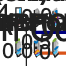

CC5_Reg005_36RollW_Output_Plot = PerformancePlot(CC_R_bcktest);

**Export **

exportName = 'CC5_Reg005_36RollW_Output_Plot.pdf';
exportgraphics(CC5_Reg005_36RollW_Output_Plot,fullfile(imageExportpath_st,exportName),'Resolution',300);

### 7. W & R

Define the portfolios to calcualte DSR for: eg selected cash constraints, reg lambdas etc

CC = 1; % no constraint if == 1
W_sd = 2; % exclude if no winsorising is wanted

HSFPparameters_test = HSFPparameters;
HSFPparameters_test.Tau_prior = 36;
test_class7 = backtestedPortfolios;
test_class7.HSFPparameters = HSFPparameters_test;
test_class7.Returns = M_Ret_TT;
test_class7.Method =  'none';
test_class7.Signals = timetable(SIG_SMOOTHED_TT.Time, SIG_SMOOTHED_TT.SAVIT40_Index, SIG_SMOOTHED_TT.lagged_SACPIYOY_Index);
test_class7.WinsorStd = W_sd;
test_class7.CashConstriant = CC;
test_class7.RegLambda = 0.005;

W_R_bcktest = OOPbacktest_analysis(test_class7);

Sub SR* into PSR to calculated DSR:

MV_W_R_dsr = psr(W_R_bcktest.ExcessReturns(:,2), MVexpected_max_sr)
HRP_W_R_dsr = psr(W_R_bcktest.ExcessReturns(:,4), MVexpected_max_sr)

W2_Reg005_36RollW_Output_Plot = PerformancePlot(W_R_bcktest);

**Export **

exportName = 'W2_Reg005_36RollW_Output_Plot.pdf';
exportgraphics(W2_Reg005_36RollW_Output_Plot,fullfile(imageExportpath_st,exportName),'Resolution',300);

### 8. CC, W & R

Define the portfolios to calcualte DSR for: eg selected cash constraints, reg lambdas etc

CC = 0.05; % no constraint if == 1
W_sd = 2; % exclude if no winsorising is wanted
HSFPparameters_test = HSFPparameters;

MV_CC_R_dsr = 0.9021

HSFPparameters_test.Tau_prior = 36;

HRP_CC_R_dsr = 0.9114

test_class8 = backtestedPortfolios;
test_class8.HSFPparameters = HSFPparameters_test;
test_class8.Returns = M_Ret_TT;
test_class8.Method =  'none';
test_class8.Signals = timetable(SIG_SMOOTHED_TT.Time, SIG_SMOOTHED_TT.SAVIT40_Index, SIG_SMOOTHED_TT.lagged_SACPIYOY_Index);

test_class8.WinsorStd = W_sd;
test_class8.CashConstriant = CC;
test_class8.RegLambda = 0.005;

CC_W_R_bcktest = OOPbacktest_analysis(test_class8);

Sub SR* into PSR to calculated DSR:

MV_CC_W_R_dsr = psr(CC_W_R_bcktest.ExcessReturns(:,2), MVexpected_max_sr)
HRP_CC_W_R_dsr = psr(CC_W_R_bcktest.ExcessReturns(:,4), MVexpected_max_sr)

CC5_W2_Reg005_36RollW_Output_Plot = PerformancePlot(CC_W_R_bcktest);

**Export **

exportName = 'CC5_W2_Reg005_36RollW_Output_Plot.pdf';
exportgraphics(CC5_W2_Reg005_36RollW_Output_Plot,fullfile(imageExportpath_st,exportName),'Resolution',300);

## 7. Benchmark DSRs

### 1. Equally Weighted

Sub SR* into PSR to calculated DSR:

MV_W_R_dsr = 0.8917

HRP_W_R_dsr = 0.9604

MV_CC_W_R_dsr = 0.9215

HRP_CC_W_R_dsr = 0.9630

EW_dsr = 0.9745

BF_BH_dsr = 0.9552

BF_CM_dsr = 0.9644

EW_dsr = psr(CC_W_bcktest.ExcessReturns(:,1), 0)
BF_BH_dsr = psr(CC_W_bcktest.ExcessReturns(:,3), MVexpected_max_sr)
BF_CM_dsr = psr(CC_W_bcktest.ExcessReturns(:,5), MVexpected_max_sr)
% ALSI_dsr = psr(unadjusted_bcktest.ExcessReturns(:,4), MVexpected_max_sr)
% ALBI_dsr = psr(unadjusted_bcktest.ExcessReturns(:,4), MVexpected_max_sr)
% Cash_dsr = psr(unadjusted_bcktest.ExcessReturns(:,4), MVexpected_max_sr)